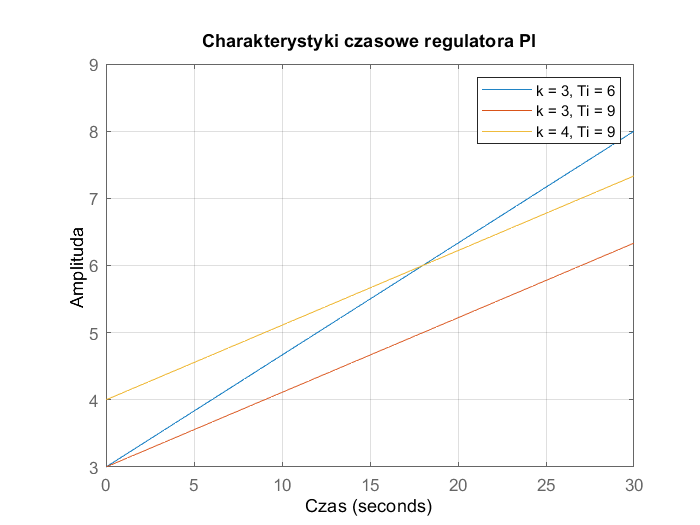

% Regulator PI
k1 = 3;
Ti1 = 6;
licz1 = [k1*Ti1, 1];
mian1 = [Ti1, 0];

k2 = 3;
Ti2 = 9;
licz2 = [k2*Ti2, 1];
mian2 = [Ti2, 0];

k3 = 4;
Ti3 = 9;
licz3 = [k3*Ti3, 1];
mian3 = [Ti3, 0];

t = linspace(0, 30);
figure
hold on
step(licz1, mian1, t);
step(licz2, mian2, t);
step(licz3, mian3, t);
grid on
title('Charakterystyki czasowe regulatora PI')
xlabel('Czas')
ylabel('Amplituda')
legend('k = 3, Ti = 6', 'k = 3, Ti = 9', 'k = 4, Ti = 9')

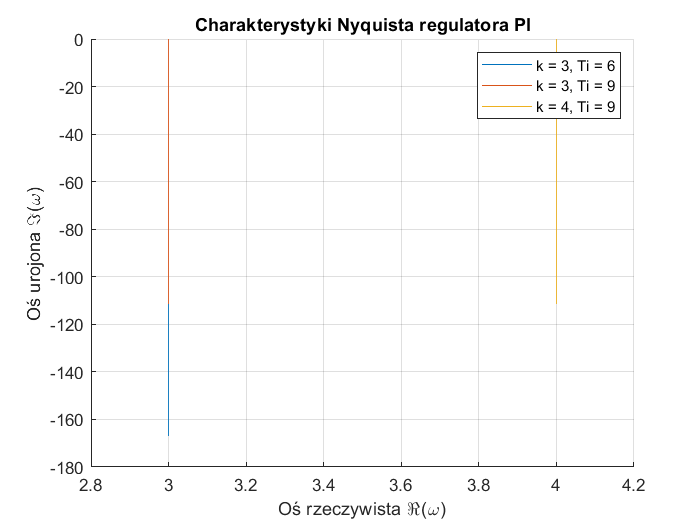


[Re1, Im1] = nyquist(licz1, mian1);
[Re2, Im2] = nyquist(licz2, mian2);
[Re3, Im3] = nyquist(licz3, mian3);

figure
hold on
plot(Re1(:), Im1(:))
plot(Re2(:), Im2(:))
plot(Re3(:), Im3(:))
grid on
title('Charakterystyki Nyquista regulatora PI')
xlabel('Oś rzeczywista \Re(\omega)')
ylabel('Oś urojona \Im(\omega)')
legend('k = 3, Ti = 6', 'k = 3, Ti = 9', 'k = 4, Ti = 9')

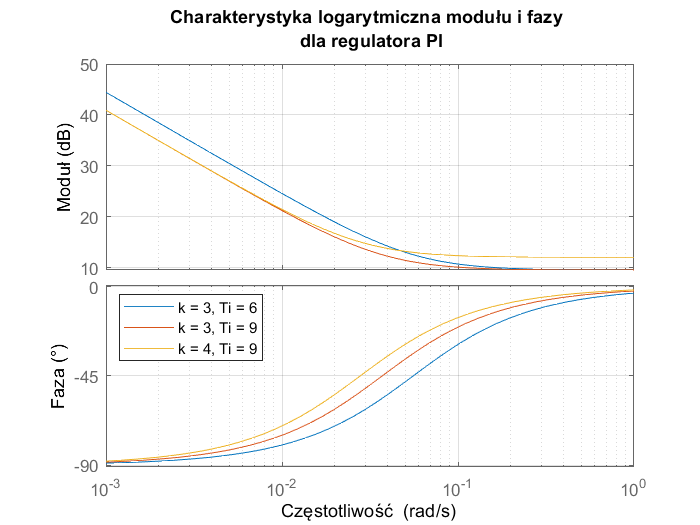


figure
hold on
bode(licz1, mian1)
bode(licz2, mian2)
bode(licz3, mian3)
title(sprintf("Charakterystyka logarytmiczna modułu i fazy \n dla regulatora PI"))
xlabel("Częstotliwość")
axes=findobj('type','axes');
h_magnitude=get(axes(2),'YLabel');
h_phase=get(axes(1),'YLabel');
set(h_magnitude,'String','Moduł (dB)')
set(h_phase,'String','Faza (°)')
legend('k = 3, Ti = 6', 'k = 3, Ti = 9', 'k = 4, Ti = 9', 'Location', 'NorthWest')
grid on

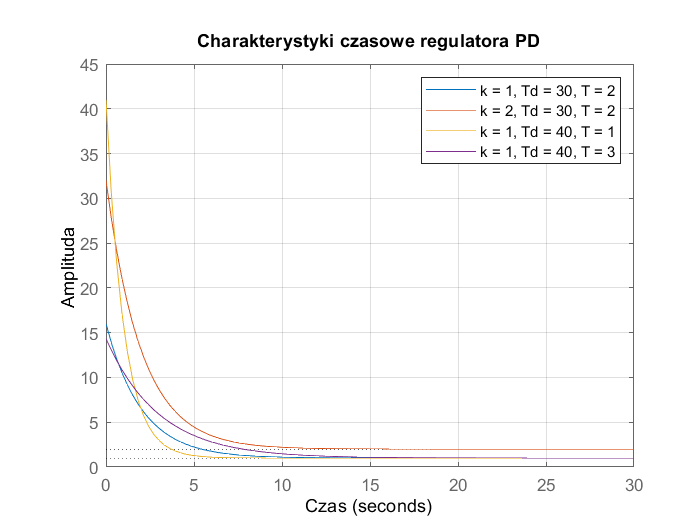

% Regulator PD
k1 = 1;
Td1 = 30;
T1 = 2;
licz1 = [k1*(Td1 + T1), k1];
mian1 = [T1, 1];

k2 = 2;
Td2 = 30;
T2 = 2;
licz2 = [k2*(Td2 + T2), k2];
mian2 = [T2, 1];

k3 = 1;
Td3 = 40;
T3 = 1;
licz3 = [k3*(Td3 + T3), k3];
mian3 = [T3, 1];

k4 = 1;
Td4 = 40;
T4 = 3;
licz4 = [k4*(Td4 + T4), k4];
mian4 = [T4, 1];

t = linspace(0, 30);
figure
hold on
step(licz1, mian1, t);
step(licz2, mian2, t);
step(licz3, mian3, t);
step(licz4, mian4, t);
grid on
title('Charakterystyki czasowe regulatora PD')
xlabel('Czas')
ylabel('Amplituda')
legend('k = 1, Td = 30, T = 2', 'k = 2, Td = 30, T = 2', 'k = 1, Td = 40, T = 1', 'k = 1, Td = 40, T = 3')

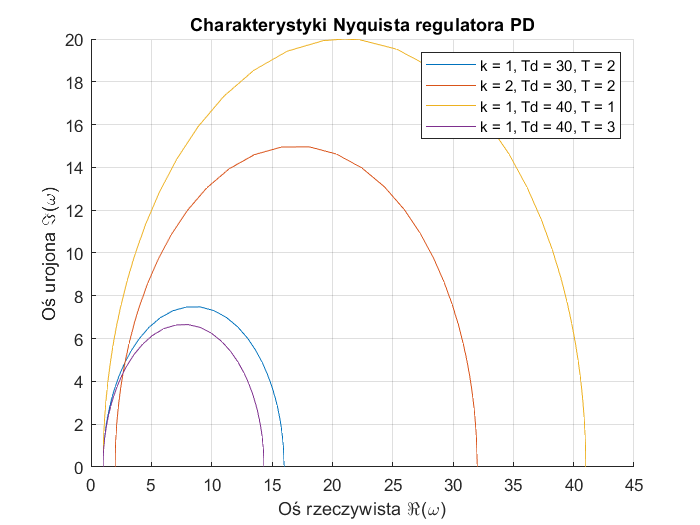


[Re1, Im1] = nyquist(licz1, mian1);
[Re2, Im2] = nyquist(licz2, mian2);
[Re3, Im3] = nyquist(licz3, mian3);
[Re4, Im4] = nyquist(licz4, mian4);
figure
hold on
plot(Re1(:), Im1(:))
plot(Re2(:), Im2(:))
plot(Re3(:), Im3(:))
plot(Re4(:), Im4(:))
grid on
title('Charakterystyki Nyquista regulatora PD')
xlabel('Oś rzeczywista \Re(\omega)')
ylabel('Oś urojona \Im(\omega)')
legend('k = 1, Td = 30, T = 2', 'k = 2, Td = 30, T = 2', 'k = 1, Td = 40, T = 1', 'k = 1, Td = 40, T = 3')

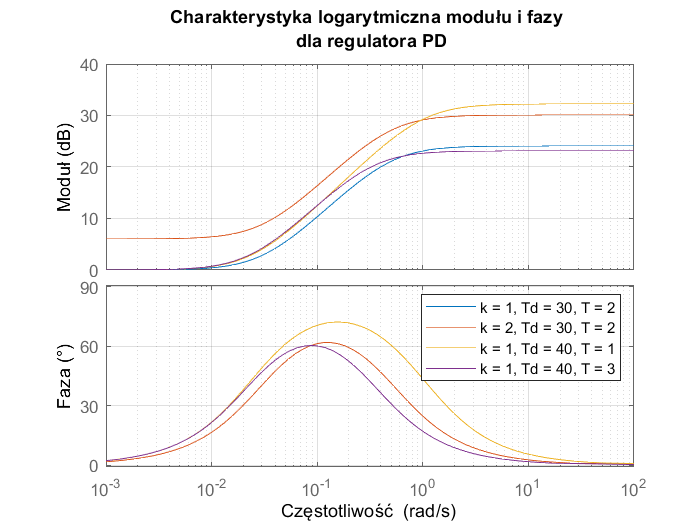


figure
hold on
bode(licz1, mian1)
bode(licz2, mian2)
bode(licz3, mian3)
bode(licz4, mian4)
title(sprintf("Charakterystyka logarytmiczna modułu i fazy \n dla regulatora PD"))
xlabel("Częstotliwość")
axes=findobj('type','axes');
h_magnitude=get(axes(2),'YLabel');
h_phase=get(axes(1),'YLabel');
set(h_magnitude,'String','Moduł (dB)')
set(h_phase,'String','Faza (°)')
legend('k = 1, Td = 30, T = 2', 'k = 2, Td = 30, T = 2', 'k = 1, Td = 40, T = 1', 'k = 1, Td = 40, T = 3')
grid on

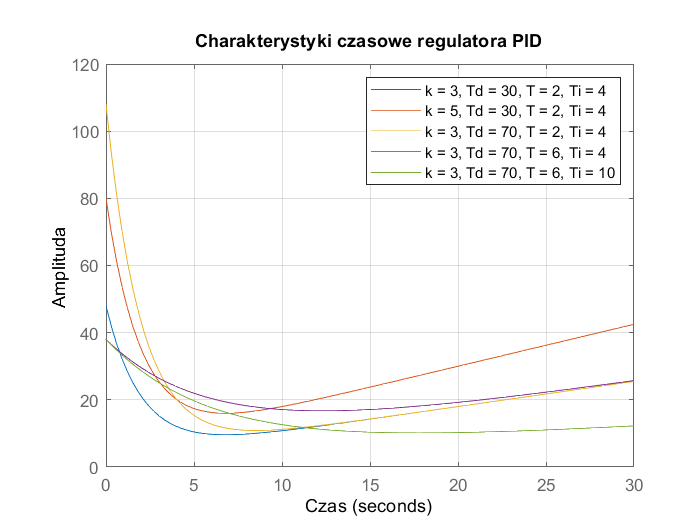

% Regulator PID
k1 = 3;
Td1 = 30;
T1 = 2;
Ti1 = 4;
licz1 = [k1 * Ti1*(T1 + Td1), k1*(T1 + Ti1), k1];
mian1 = [Ti1 * T1, Ti1, 0];

k2 = 5;
Td2 = 30;
T2= 2;
Ti2 = 4;
licz2 = [k2 * Ti2*(T2 + Td2), k2*(T2 + Ti2), k2];
mian2 = [Ti2 * T2, Ti2, 0];

k3 = 3;
Td3 = 70;
T3 = 2;
Ti3 = 4;
licz3 = [k3 * Ti3*(T3 + Td3), k3*(T3 + Ti3), k3];
mian3 = [Ti3 * T3, Ti3, 0];

k4 = 3;
Td4 = 70;
T4 = 6;
Ti4 = 4;
licz4 = [k4 * Ti4*(T4 + Td4), k4*(T4 + Ti4), k4];
mian4 = [Ti4 * T4, Ti4, 0];

k5 = 3;
Td5 = 70;
T5 = 6;
Ti5 = 10;
licz5 = [k5 * Ti5*(T5 + Td5), k5*(T5 + Ti5), k5];
mian5 = [Ti5 * T5, Ti5, 0];

t = linspace(0, 30);
figure
hold on
step(licz1, mian1, t);
step(licz2, mian2, t);
step(licz3, mian3, t);
step(licz4, mian4, t);
step(licz5, mian5, t);
grid on
title('Charakterystyki czasowe regulatora PID')
xlabel('Czas')
ylabel('Amplituda')
legend('k = 3, Td = 30, T = 2, Ti = 4', 'k = 5, Td = 30, T = 2, Ti = 4', ...
    'k = 3, Td = 70, T = 2, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 10')

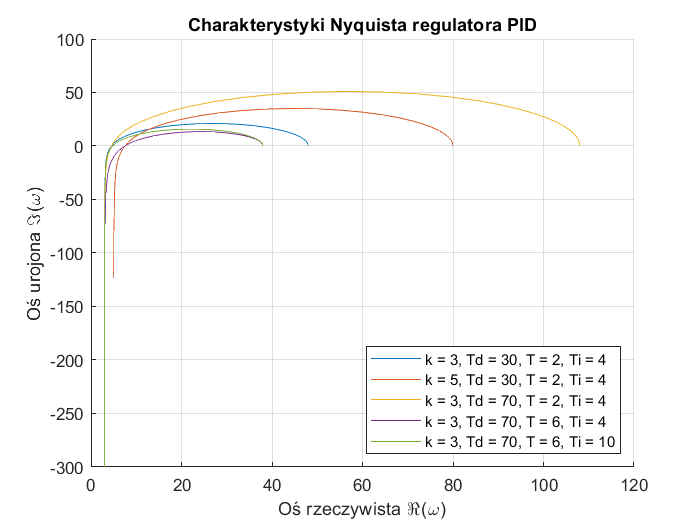


[Re1, Im1] = nyquist(licz1, mian1);
[Re2, Im2] = nyquist(licz2, mian2);
[Re3, Im3] = nyquist(licz3, mian3);
[Re4, Im4] = nyquist(licz4, mian4);
[Re5, Im5] = nyquist(licz5, mian5);
figure
hold on
plot(Re1(:), Im1(:))
plot(Re2(:), Im2(:))
plot(Re3(:), Im3(:))
plot(Re4(:), Im4(:))
plot(Re5(:), Im5(:))
grid on
title('Charakterystyki Nyquista regulatora PID')
xlabel('Oś rzeczywista \Re(\omega)')
ylabel('Oś urojona \Im(\omega)')
legend('k = 3, Td = 30, T = 2, Ti = 4', 'k = 5, Td = 30, T = 2, Ti = 4', ...
    'k = 3, Td = 70, T = 2, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 10', 'Location', 'SouthEast')

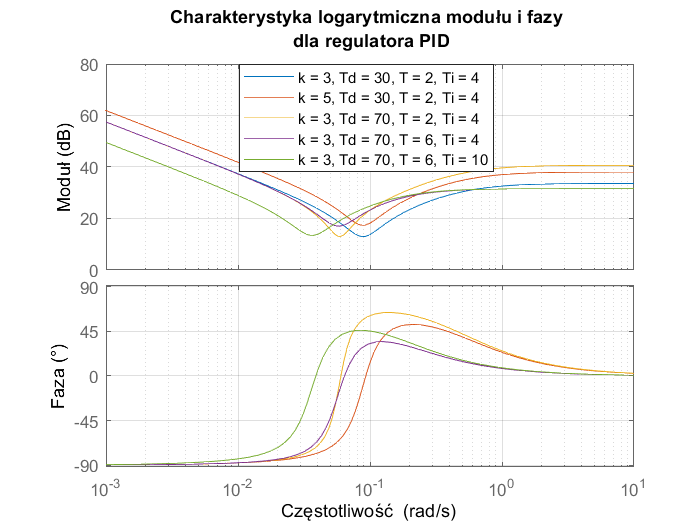


figure
hold on
bode(licz1, mian1)
bode(licz2, mian2)
bode(licz3, mian3)
bode(licz4, mian4)
bode(licz5, mian5)
title(sprintf("Charakterystyka logarytmiczna modułu i fazy \n dla regulatora PID"))
xlabel("Częstotliwość")
axes=findobj('type','axes');
h_magnitude=get(axes(2),'YLabel');
h_phase=get(axes(1),'YLabel');
set(h_magnitude,'String','Moduł (dB)')
set(h_phase,'String','Faza (°)')
legend('k = 3, Td = 30, T = 2, Ti = 4', 'k = 5, Td = 30, T = 2, Ti = 4', ...
    'k = 3, Td = 70, T = 2, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 4', 'k = 3, Td = 70, T = 6, Ti = 10')
legend('Position',[0.341309517304103 0.672793359513993 0.363928577933992 0.204761909303211])
grid on